# Continuation of quasiperiodic invariant tori

We consider a four-node network of oscillators coupled through linear spring. The damping of the first node is of van der pol type and this node subjects to external harmonic forcing. The equation of motion of this system is given as follows


$$\ddot{u}_1+(\epsilon u_1^2-1)\dot{u}_1+3u_1-u_2-u_4=\epsilon a\cos\Omega t,\\
\ddot{u}_2+0.8\dot{u}_2-u_1+4u_2-u_3-u_4=0,\\
\ddot{u}_3+0.8\dot{u}_3-u_2+2u_3=0,\\
\ddot{u}_4+0.8\dot{u}_4-u_1-u_2+3u_4=0
$$


More details about this model can be found in [1]. In this demo, we will perform

- continuation of periodic orbits with varied $\Omega$,

- continuation of torus (TR) bifurcation with varied $a$ and $\Omega$,

- continuation of tori from TR point,

- continuation of tori with fixed rotation number $\varrho$,

- continuation of tori with varied rotation number $\varrho$. 

[1] Yu Mao and Harry Dankowicz. Topology-dependent Excitation Response of

Networks of Linear and Nonlinear Oscillators

## Construct an of initial periodic orbit 

% pnames = [ om a ]
p0 = [ 2; 0.4 ];
T  = 2*pi/p0(1);
[~,x0]  = ode45(@(t,x) net(t,x,p0), 0:1000*T, zeros(8,1)); % Approximate periodic orbit of reduced system
[t0,x0] = ode45(@(t,x) net(t,x,p0), linspace(0,T,200), x0(end,:));

## Continuation of periodic orbit

prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = coco_set(prob, 'coll', 'NTST', 20);
prob = ode_isol2po(prob, '', @net, ... % @lang_DFDX, @lang_DFDP
  t0, x0, {'Om2','f'}, p0);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of periodic orbits.\n', ...
  'po');


 Run='po': Continue family of periodic orbits.



coco(prob, 'po', [], 1, {'Om2','po.period'}, [1.9 2.1]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.58e-02  2.75e+01    0.0    0.0    0.0
   1   1  9.80e-01  3.03e+00  1.23e-03  2.45e+01    0.0    0.0    0.0
   2   1  1.00e+00  5.79e-01  3.95e-05  2.40e+01    0.0    0.1    0.0
   3   1  1.00e+00  1.88e-02  4.08e-08  2.40e+01    0.0    0.1    0.0
   4   1  1.00e+00  1.95e-05  4.53e-14  2.40e+01    0.0    0.1    0.0
   5   1  1.00e+00  2.01e-11  8.28e-15  2.40e+01    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2    po.period
    0  00:00:00   2.3961e+01      1  EP      2.0020e+00   3.1385e+00
   10  00:00:03   2.6298e+01      2          2.0013e+00   3.1395e+00
   20  00:00:04   2.7744e+01      3          2.0000e+00   3.1416e+00
   30  00:00:06   2.6980e+01      4          1.9986e+00   3.1438e+00
   40  00:00:07   2.3970e+01      5          1.9975e+00   3.1455e+00
   50  00:00:08   1.9321

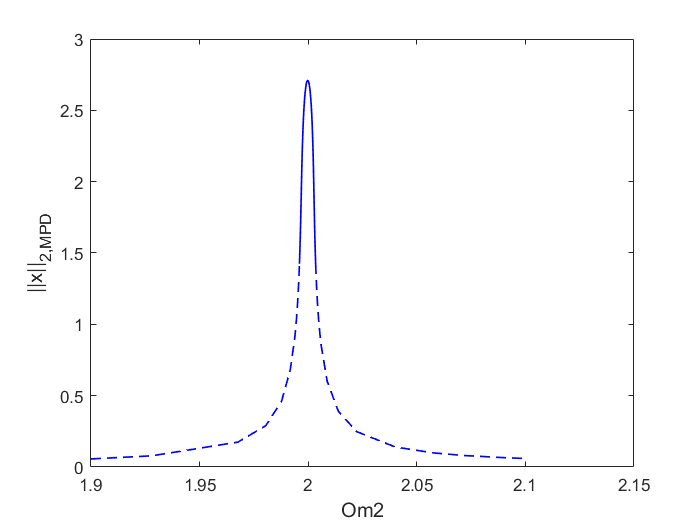


figure; coco_plot_bd('po')

## Continuation of TR bifurcation points

bd     = coco_bd_read('po');
TRlabs = coco_bd_labs(bd, 'TR');
TRlab  = max(TRlabs);
prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = ode_po2TR(prob, '', 'po', TRlab);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of TR points.\n', ...
  'po_TR');


 Run='po_TR': Continue family of TR points.



coco(prob, 'po_TR', [], 1, {'f','Om2','po.period'}, [0.4 6]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.40e-07  1.83e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE             f          Om2    po.period
    0  00:00:00   1.8301e+01      1  EP      4.0000e-01   2.0034e+00   3.1362e+00
   10  00:00:05   1.7990e+01      2          1.1530e+00   2.0111e+00   3.1243e+00
   20  00:00:11   1.7981e+01      3          3.0565e+00   2.0301e+00   3.0950e+00
   23  00:00:13   1.9547e+01      4  EP      6.0000e+00   2.0594e+00   3.0510e+00


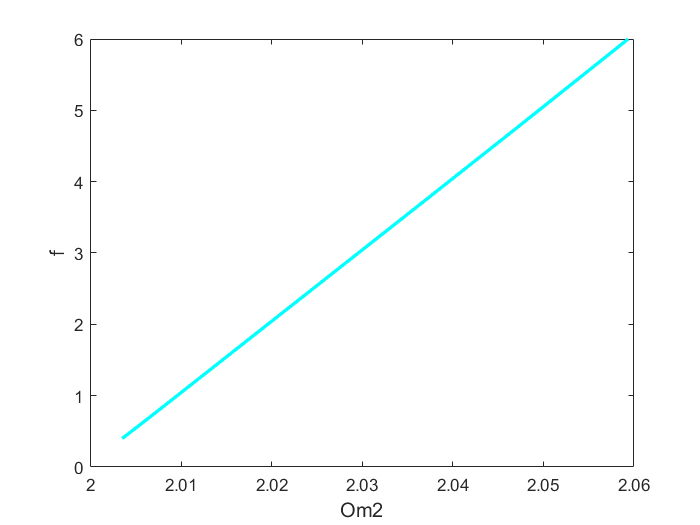

figure;
coco_plot_bd('po_TR','Om2','f')

## Continuation of tori from TR point

bd    = coco_bd_read('po_TR');
TRlab = coco_bd_labs(bd, 'EP');
TRlab = max(TRlab);
prob = coco_prob();
prob = coco_set(prob, 'tor', 'autonomous', false);
prob = coco_set(prob, 'corr', 'ItMX', 50);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 50, 'h_max', 5,...
    'h_min', 1e-6);
prob = ode_TR2tor(prob, '', 'po_TR', TRlab);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr1', TRlab, 'po_TR');


 Run='tr1': Continue torus from point 4 in run 'po_TR'.


coco(prob, 'tr1', [], 1, {'varrho','Om2','om2','om1','f'});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.42e-10  7.19e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE        varrho          Om2          om2          om1            f
    0  00:00:01   7.1897e+01      1  EP      2.8947e-02   2.0594e+00   2.0594e+00   5.9612e-02   6.0000e+00
    2  00:00:08   7.1897e+01      2  BP      2.8947e-02   2.0594e+00   2.0594e+00   5.9612e-02   6.0000e+00
   10  00:00:19   7.4017e+01      3          3.0112e-02   2.0618e+00   2.0618e+00   6.2087e-02   6.0000e+00
   20  00:00:33   8.7806e+01      4          4.6375e-02   2.0970e+00   2.0970e+00   9.7247e-02   6.0000e+00
   30  00:00:47   9.3346e+01      5          6.6527e-02   2.1423e+00   2.1423e+00   1.4252e-01   6.0000e+00
   40  00:01:01   9.7997e+01      6          8.5087e-02   2.1857e+00   2.1857e+00   1.8597e-01   6.0000e+00
   50  00:01:15   1.0702e+02    

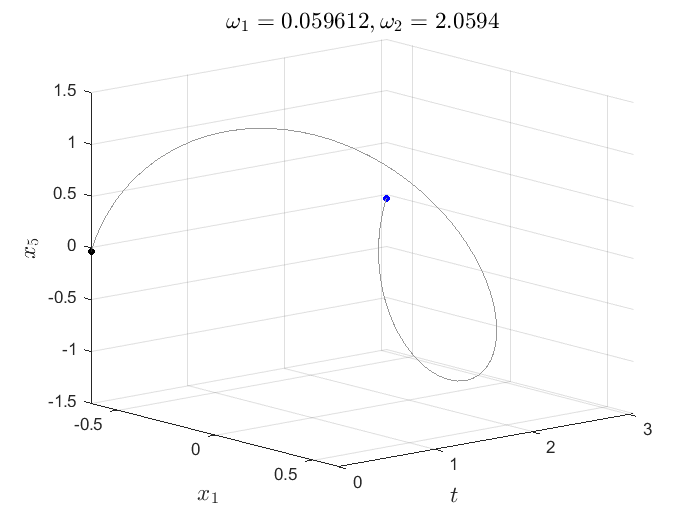

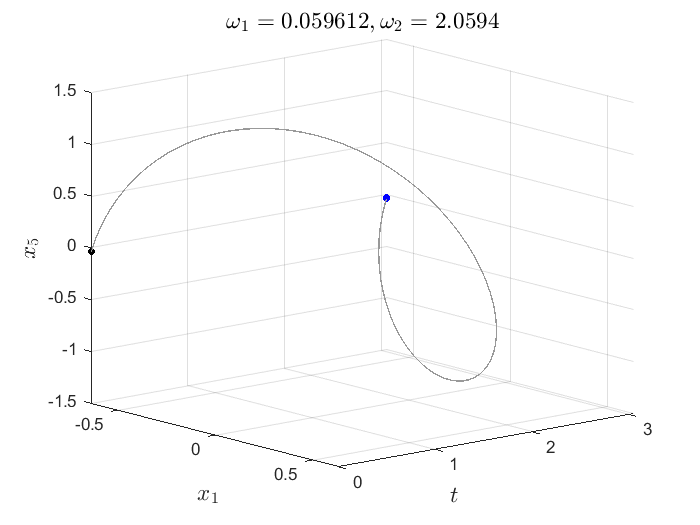

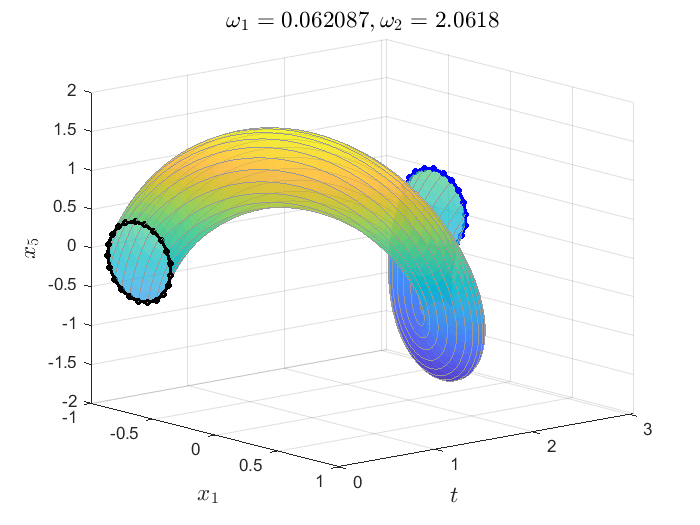

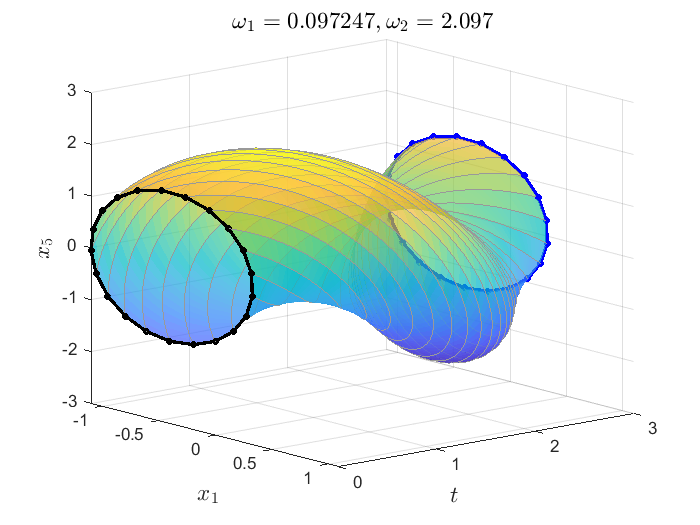

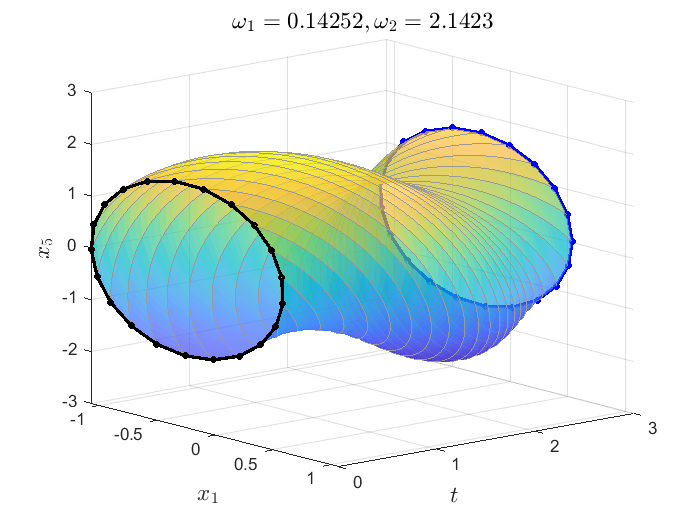

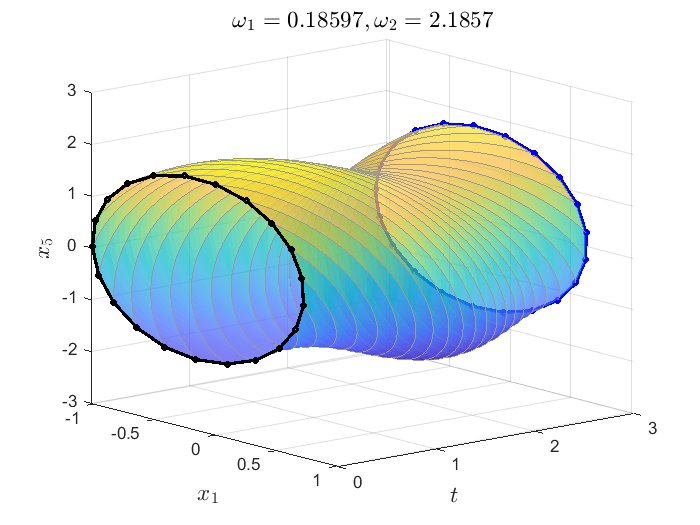

for lab = 1:6
    plot_torus('','tr1',lab,[1 5]); pause(1);
end

## Continuation of torus with fixed $\varrho$

lab  = 6;
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 100, 'h_max', 50);
prob = ode_tor2tor(prob, '', 'tr1', lab);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr2', lab, 'tr1');


 Run='tr2': Continue torus from point 6 in run 'tr1'.


coco(prob, 'tr2', [], 1, {'f','Om2','om2','om1','varrho'},[0.4 6]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          9.88e-14  9.82e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE             f          Om2          om2          om1       varrho
    0  00:00:01   9.8180e+01      1  EP      6.0000e+00   2.1857e+00   2.1857e+00   1.8597e-01   8.5087e-02
   10  00:00:11   8.9346e+01      2  EP      4.0000e-01   2.1857e+00   2.1857e+00   1.8597e-01   8.5087e-02


## Continuation of torus with varied $\varrho$

bd  = coco_bd_read('tr2');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 100, 'h_max', 50);
prob = ode_tor2tor(prob, '', 'tr2', lab);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr3', lab, 'tr2');


 Run='tr3': Continue torus from point 2 in run 'tr2'.


coco(prob, 'tr3', [], 1, {'Om2','om2','om1','varrho','f'},[2.0 2.2172]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.01e-13  8.93e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2          om2          om1       varrho            f
    0  00:00:01   8.9345e+01      1  EP      2.1857e+00   2.1857e+00   1.8597e-01   8.5087e-02   4.0000e-01
   10  00:00:12   8.9462e+01      2          2.0626e+00   2.0626e+00   6.2893e-02   3.0492e-02   4.0000e-01
   20  00:00:26   8.9253e+01      3          2.0246e+00   2.0246e+00   2.4893e-02   1.2295e-02   4.0000e-01
   30  00:00:40   8.4924e+01      4          2.0067e+00   2.0067e+00   6.8322e-03   3.4046e-03   4.0000e-01
   40  00:00:54   7.7141e+01      5          2.0043e+00   2.0043e+00   4.1563e-03   2.0737e-03   4.0000e-01
   50  00:01:08   6.7510e+01      6          2.0036e+00   2.0036e+00   3.5478e-03   1.7707e-03   4.0000e-01
   60  00:01:21   6.5104e+01    

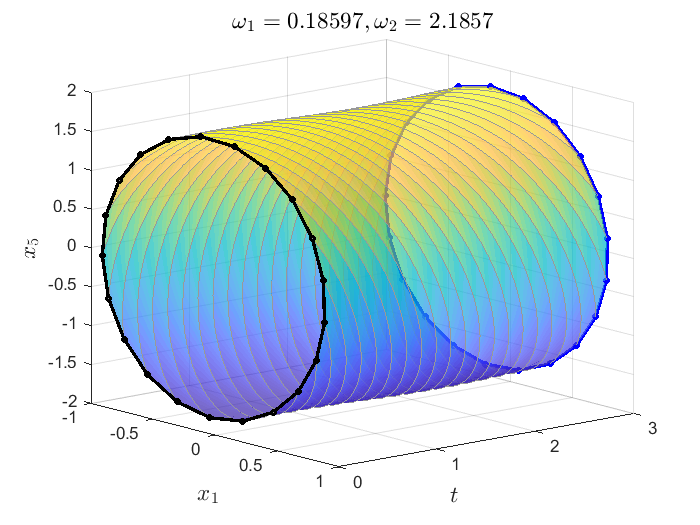

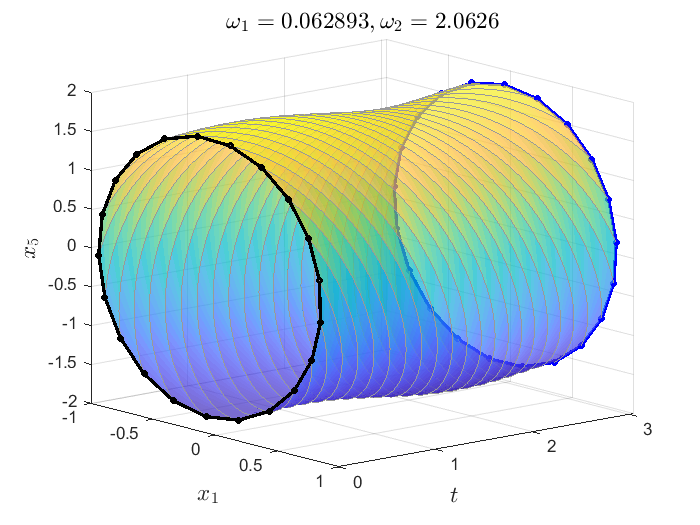

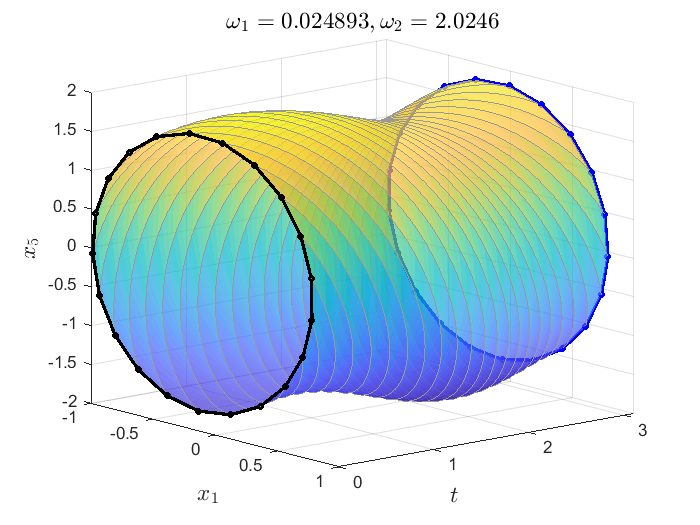

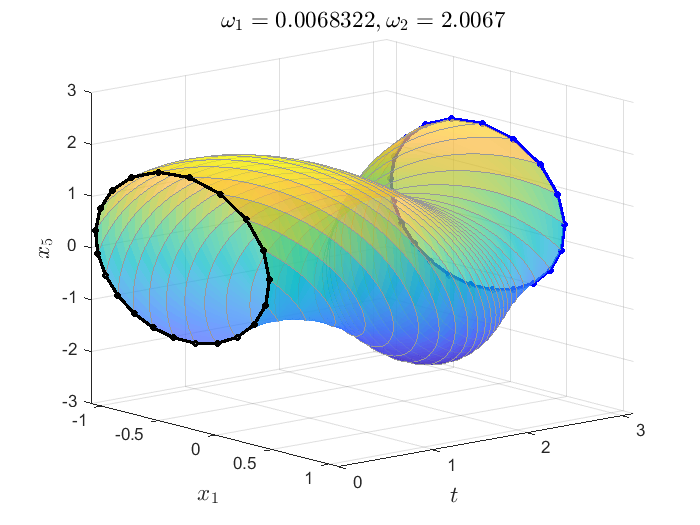

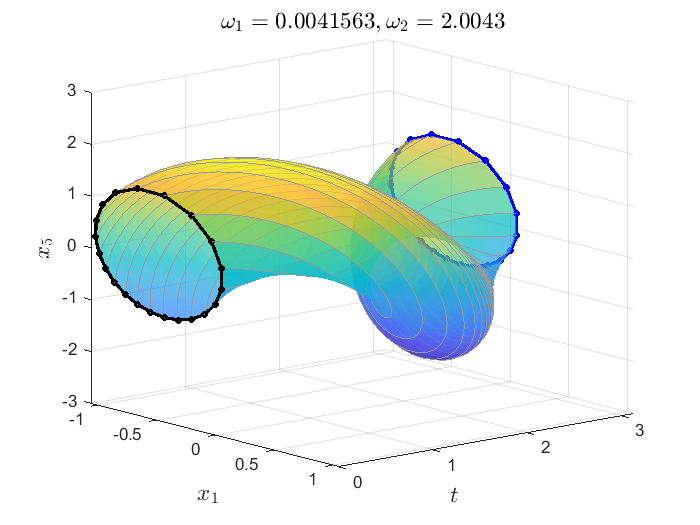

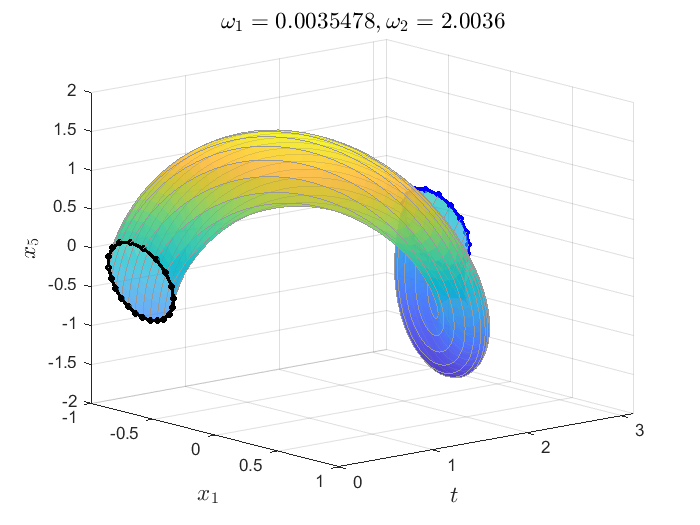

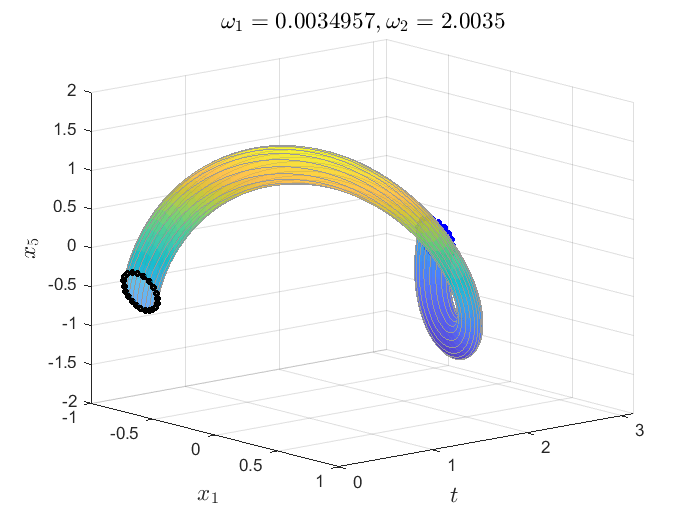

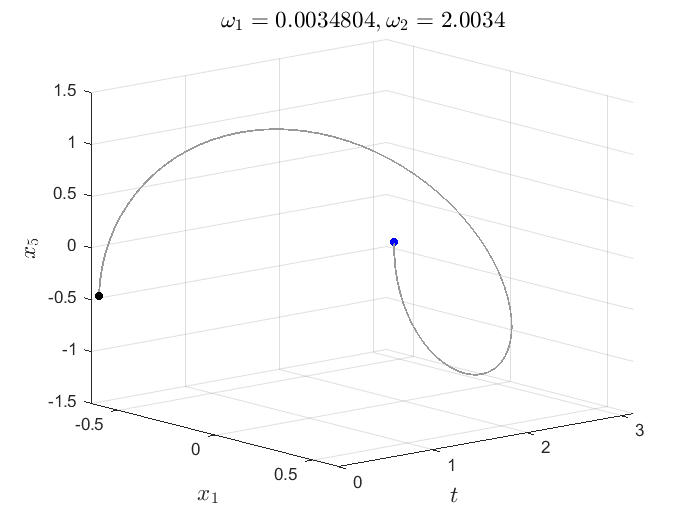

for lab = 1:11
    plot_torus('','tr3',lab,[1 5]); pause(1);
end

## Comparison with numerical integration

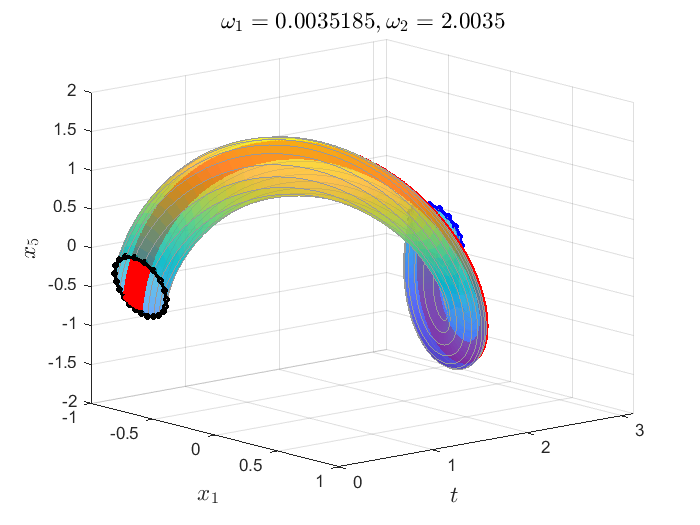

% time integration
lab = 11;
plot_torus('','tr3', lab, [1 5]);hold on
sol = tor_read_solution('','tr3',lab);
p   = sol.p(1:end-3);
xbp = sol.xbp;
T   = 2*pi/sol.p(end-1);
[t,x] = ode45(@(t,x) net(t,x,p), 0:0.01:100*T, xbp(1,:,1));
plot3(x(:,1),mod(t,T),x(:,5),'r.');